# Quadruped Robot Locomotion Using DDPG Agent

This example shows how to train a quadruped robot to walk using a deep deterministic policy gradient (DDPG) agent. The robot in this example is modeled using Simscape™ Multibody™. For more information on DDPG agents, see [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_66c8fe60-f58e-4bdb-904a-21d442f0a879).

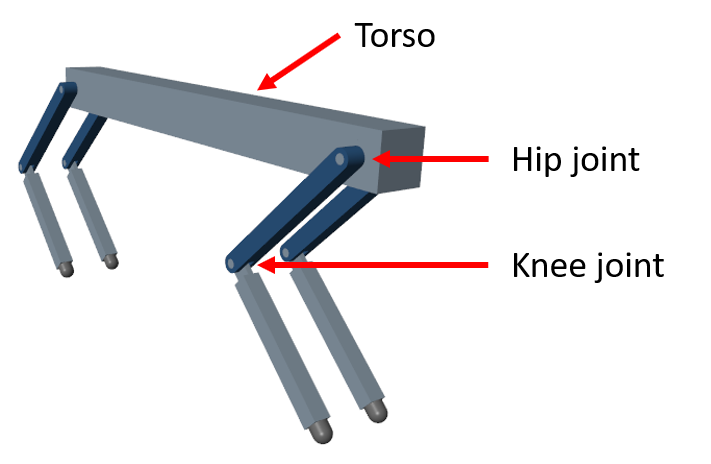

The example code may involve computation of random numbers at various stages such as initialization of the agent, creation of the actor and critic, resetting the environment during simulations, generating observations (for stochastic environments), generating exploration actions, and sampling min-batches of experiences for learning. Fixing the random number stream preserves the sequence of the random numbers every time you run the code and improves reproducibility of results. You will fix the random number stream at various locations in the example. 

## Fix Random Seed Generator to Improve Reproducibility

Fix the random number stream with the seed `0` and random number algorithm Mersenne Twister. For more information on random number generation see [`rng`](docid:matlab_ref#bsuymc2-1).

previousRngState = rng(0,"twister")

previousRngState = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]


The output `previousRngState` is a structure that contains information about the previous state of the stream. You will restore the state at the end of the example. 

Load the necessary parameters into the base workspace in MATLAB® using the Script `initializeRobotParameters` provided with the example.

initializeRobotParameters;

## Quadruped Robot Model

The environment for this example is a quadruped robot, and the training goal is to make the robot walk in a straight line using minimal control effort.

Open the model. 

mdl = "rlQuadrupedRobot";


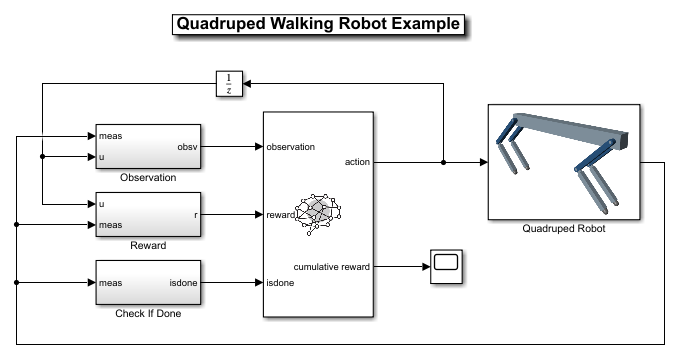

The robot is modeled using Simscape™ Multibody™ with its main structural components consisting of four legs and a torso. The legs are connected to the torso through revolute joints that enable rotation of the legs with respect to the torso. The joints are actuated by torque signals provided by the RL Agent.

#### Observations

The robot environment provides 44 observations to the agent, each normalized between –1 and 1. These observations are:

- Y (vertical) and Y (lateral) position of the torso center of mass

- Quaternion representing the orientation of the torso

- X (forward), Y (vertical), and Z (lateral) velocities of the torso at the center of mass

- Roll, pitch, and yaw rates of the torso

- Angular positions and velocities of the hip and knee joints for each leg

- Normal and friction force due to ground contact for each leg

- Action values (torque for each joint) from the previous time step

For all four legs, the initial values for the hip and knee joint angles are set to –0.8234 and 1.6468 radians, respectively. The neutral positions of the joints are set at 0 radian. The legs are in neutral position when they are stretched to their maximum and are aligned perpendicularly to the ground.

#### Actions

The agent generates eight actions normalized between –1 and 1. After multiplying with a scaling factor, these correspond to the eight joint torque signals for the revolute joints. The overall joint torque bounds are +/– 10 N·m for each joint.

#### Reward

The following reward is provided to the agent at each time step during training. This reward function encourages the agent to move forward by providing a positive reward for positive forward velocity. It also encourages the agent to avoid early termination by providing a constant reward ($25 T_s/T_f$) at each time step. The remaining terms in the reward function are penalties that discourage unwanted states, such as large deviations from the desired height and orientation or the use of excessive joint torques.


$$r_t = v_x + 25 \frac{T_s}{T_f} - 50 \hat{y}^2 - 20 \theta^2 - 0.02 \sum_i{u_{t-1}^i}^2$$


where

- $v_x$ is the velocity of the torso's center of mass in the x-direction.

- $T_s$ and $T_f$ are the sample time and final simulation time of the environment, respectively.

- $\hat{y}$ is the scaled height error of the torso's center of mass from the desired height of 0.75 m.

- $\theta$ is the pitch angle of the torso.

- $u_{t-1}^i$is the action value for joint $i$ from the previous time step.

#### Episode Termination

During training or simulation, the episode terminates if any of the following situations occur.

- The height of the torso center of mass from the ground is below 0.5 m (fallen).

- The head or tail of the torso is below the ground.

- Any knee joint is below the ground.

- Roll, pitch, or yaw angles are outside bounds (+/– 0.1745, +/– 0.1745, and +/– 0.3491 radians, respectively).

## Create Environment Object

Specify the parameters for the observation set.

numObs = 44;
obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = "observations";

Specify the parameters for the action set.

numAct = 8;
actInfo = rlNumericSpec([numAct 1],LowerLimit=-1,UpperLimit=1);
actInfo.Name = "torque";

 Create the environment using the reinforcement learning model.

blk = mdl + "/RL Agent";
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);

During training, the function `quadrupedResetFcn` provided at the end of the example introduces random deviations into the initial joint angles and angular velocities.

env.ResetFcn = @quadrupedResetFcn;

## Create DDPG Agent Object

DDPG agents use a parametrized Q-value function approximator as a critic, to estimate the value of the policy. They also use a parametrized deterministic policy over continuous action spaces, which is learned by a continuous deterministic actor. 

For more information on creating a deep neural network value function, see [Create Policy and Value Function Functions](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004). For an example that creates neural networks for DDPG agents, see [Train DDPG Agent to Control Double Integrator System](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

First specify the following options for training the agent. For more information see [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

- Specify a capacity of 1e6 for the experience buffer to store a diverse set of experiences.

- Specify the `MaxMiniBatchPerEpoch` value to perform a maximum of 200 gradient step updates for each learning iteration.

- Specify a mini-batch size of 256 for learning. Smaller mini-batches are computationally efficient but may introduce variance in training. Contrarily, larger batch sizes can make the training stable but require higher memory.

- Specify a learning rate of 1e-3 for the agent's actor and critic optimizer algorithms. A large learning rate causes drastic updates which may lead to divergent behaviors, while a low value may require many updates before reaching the optimal point.

- Specify a gradient threshold value of 1.0 to clip the computed gradients to enhance the stability of the learning algorithm.

- Specify a standard deviation of 0.1 and mean attraction coefficient of 1.0 to improve exploration of the agent's action space.

- Specify a sample time Ts=0.025s.

% create the agent options object
agentOptions = rlDDPGAgentOptions();

% specify the options
agentOptions.SampleTime = Ts;
agentOptions.MiniBatchSize = 256;
agentOptions.ExperienceBufferLength = 1e6;
agentOptions.MaxMiniBatchPerEpoch = 200;

% optimizer options
agentOptions.ActorOptimizerOptions.LearnRate = 1e-3;
agentOptions.ActorOptimizerOptions.GradientThreshold = 1;
agentOptions.CriticOptimizerOptions.LearnRate = 1e-3;
agentOptions.CriticOptimizerOptions.GradientThreshold = 1;

% exploration options
agentOptions.NoiseOptions.StandardDeviation = 0.1;
agentOptions.NoiseOptions.MeanAttractionConstant = 1.0; 

When you create the agent, the initial parameters of the actor and critic networks are initialized with random values. Fix the random number stream so that the agent is always initialized with the same parameter values.

rng(0,"twister");

Create the `rlDDPGAgent` object for the agent with `256` hidden units per layer.

initOpts = rlAgentInitializationOptions(NumHiddenUnit=256);
agent = rlDDPGAgent(obsInfo,actInfo,initOpts,agentOptions);

## Specify Training Options

To train the agent, first specify the following training options:

- Run each training episode for at most 10,000 episodes, with each episode lasting at most `maxSteps` time steps.

- Display the training progress in the Reinforcement Learning Training Monitor dialog box (set the `Plots` option).

- Stop training when the greedy policy evaluation exceeds 300.

trainOpts = rlTrainingOptions(...
    MaxEpisodes=10000,...
    MaxStepsPerEpisode=floor(Tf/Ts),...
    ScoreAveragingWindowLength=250,...
    Plots="training-progress",...
    StopTrainingCriteria="EvaluationStatistic",...
    StopTrainingValue=1500);

To train the agent in parallel, specify the following training options. Training in parallel requires Parallel Computing Toolbox™ software. If you do not have Parallel Computing Toolbox™ software installed, set `UseParallel` to `false`. 

- Set the `UseParallel` option to t`rue`.

- Train the agent using asynchronous parallel workers.

trainOpts.UseParallel = true;
trainOpts.ParallelizationOptions.Mode = "async";

For more information see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

In parallel training, workers simulate the agent's policy with the environment and store experiences in the replay memory. When workers operate asynchronously the order of stored experiences may not be deterministic and can ultimately make the training results different. To maximize the reproducibility likelihood:

- Initialize the parallel pool with the same number of parallel workers every time you run the code. For information on specifying the pool size see [Discover Clusters and Use Cluster Profiles](docid:distcomp_ug#f5-16141).

- Use synchronous parallel training by setting `trainOpts.ParallelizationOptions.Mode` to `"sync"`.

- Assign a random seed to each parallel worker using `trainOpts.ParallelizationOptions.WorkerRandomSeeds`. The default value of -1 assigns a unique random seed to each parallel worker.

## Train Agent

Fix the random stream for reproducibility.

rng(0,"twister");

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Due to the complexity of the robot model, this process is computationally intensive and takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`. 

doTraining = true;
if doTraining    
    % Evaluate the greedy policy performance by taking the cumulative
    % reward mean over 5 simulations every 25 training episodes.
    evaluator = rlEvaluator(NumEpisodes=5, EvaluationFrequency=25);
    % Train the agent.
    result = train(agent, env, trainOpts, Evaluator=evaluator);
    save("FrontnBackSync1.mat","agent")
else
    % Load pretrained agent parameters for the example.
    load("rlQuadrupedAgentParams.mat","params") % can load this from anny source
    setLearnableParameters(agent, params);
end

Error using rl.internal.trainmgr.context.OnlineTrainingContext/setupEnv (line 106)
The model 'rlQuadrupedRobot' has unsaved changes. The model must be saved before running parallel simulations.

Error in rl.internal.train.OffPolicyTrainer/run_internal_ (

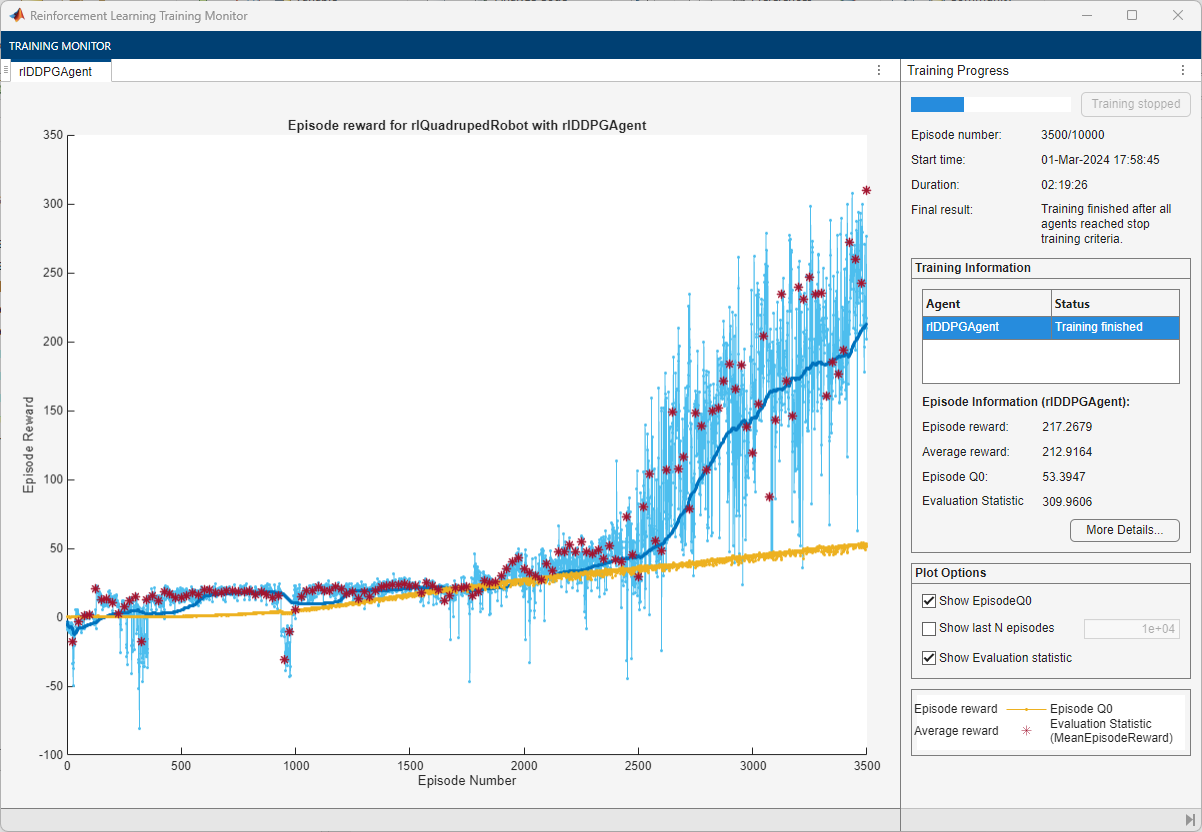

## Simulate Trained Agent

Fix the random stream for reproducibility.

rng(0,"twister");

To validate the performance of the trained agent, simulate it within the robot environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

load("FrontnBackSync.mat","agent")

simOptions = rlSimulationOptions(MaxSteps=floor(Tf/Ts));
experience = sim(env,agent,simOptions);

save("FrontnBackSync.mat","agent")

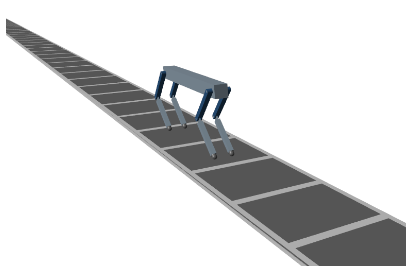

Restore the random number stream using the information stored in `previousRngState`.

rng(previousRngState);

## Reset Function

function in = quadrupedResetFcn(in)
% Randomize initial conditions.

l1 = evalin('base','l1');
l2 = evalin('base','l2');

max_foot_disp_x = 0.1;
min_body_height = 0.7;
max_body_height = 0.8;
max_speed_x = 0.05;
max_speed_y = 0.025;

if rand < 0.5
    % Start from random initial conditions

    % Randomize height
    b = min_body_height + (max_body_height - min_body_height) * rand;

    % Randomize x-displacement of foot from hip joint
    a = -max_foot_disp_x + 2 * max_foot_disp_x * rand(1,4);

    % Calculate joint angles
    d2r = pi/180;
    th_FL = d2r * quadrupedInverseKinematics(a(1),-b,l1,l2);
    th_FR = d2r * quadrupedInverseKinematics(a(2),-b,l1,l2);
    th_RL = d2r * quadrupedInverseKinematics(a(3),-b,l1,l2);
    th_RR = d2r * quadrupedInverseKinematics(a(4),-b,l1,l2);

    % Adjust for foot height
    foot_height = ...
        0.05*l2*(1-sin(2*pi-(3*pi/2+sum([th_FL;th_FR;th_RL;th_RR],2))));
    y_body = max(b) + max(foot_height);

    % Randomize body velocities
    vx = 2 * max_speed_x * (rand-0.5);
    vy = 2 * max_speed_y * (rand-0.5);

else
    % Start from fixed initial conditions

    y_body = 0.7588;
    th_FL = [-0.8234 1.6468];
    th_FR = th_FL;
    th_RL = th_FL;
    th_RR = th_FL;
    vx = 0;
    vy = 0;
end

in = setVariable(in,'y_init',y_body);
in = setVariable(in,'init_ang_FL',th_FL);
in = setVariable(in,'init_ang_FR',th_FR);
in = setVariable(in,'init_ang_RL',th_RL);
in = setVariable(in,'init_ang_RR',th_RR);
in = setVariable(in,'vx_init',vx);
in = setVariable(in,'vy_init',vy);
end

## References

[1] Heess, Nicolas, Dhruva TB, Srinivasan Sriram, Jay Lemmon, Josh Merel, Greg Wayne, Yuval Tassa, et al. ‘Emergence of Locomotion Behaviours in Rich Environments’. *ArXiv:1707.02286 [Cs]*, 10 July 2017. [https://arxiv.org/abs/1707.02286](https://arxiv.org/abs/1707.02286).

*Copyright 2019-2024 The MathWorks, Inc.*